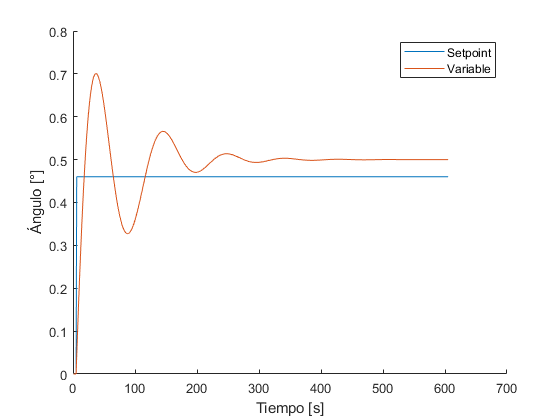

clear all
load Datos.mat

hold on
x= [0,0,0,0,0,u];
y= [0,0,0,0,0,deseados];
plot(x)
plot(y)

% plot(ControlOutput)
ylabel("Ángulo [°]");
xlabel("Tiempo [s]");
legend("Setpoint","Variable");


% Parte 2
alfa=0.1;
% deseados=0;
Aux=0

Aux = 0



% w=[0.0003,0.0003,0.0000,-0.9441,1.9433];
% entradas=0;
% deseados=0;
randindex=randperm(length(y)-3);
for i=1:length(y)-3
 
 j=randindex(i);
entradas(:,j)=[y(j:j+3)';x(j:j+2)'];
entradas(:,j)=entradas(:,j).*(1+0.00001.*(rand(7,1)-0.5));

deseados(:,j) = x(j+3);
end

no=10;
nd = size(entradas,2);
ne = size(entradas,1);
ns = size(deseados,1);

w2 = rand(no+1,ns);
c2 = rand(ne,no)-0.5;
d2=rand(no,1)./1;

[tnEntradas,vEntradas,tEntradas,itnEntradas,ivEntradas,itEntradas] ...
 = dividerand(entradas,1,0,0);
tnDeseados=deseados(:,itnEntradas);
vDeseados=deseados(:,ivEntradas);
tDeseados=deseados(:,itEntradas);

nit=10000;
for i=1:nit
[yrkTn, ecmTrain(:,i),w2,c2] = feedForwardBRN(tnEntradas,ne,no,c2,d2,w2,tnDeseados,alfa,ns,nd,1);

[yrkV, ecmValidacion(:,i)] = feedForwardBRN(tnEntradas,ne,no,c2,d2,w2,tnDeseados,alfa,ns,nd,0);
% [M,I]=sort(Aux,'descend');
end
% [yrkTest, ecmTest] = feedForwardBRN(tEntradas,ne,no,c2,d2,w2,tDeseados,alfa,ns,nd,0);

## Parte 4: Grafico resultados.

fprintf('Graficando errores cuadráticos medio ...\n')

Graficando errores cuadráticos medio ...


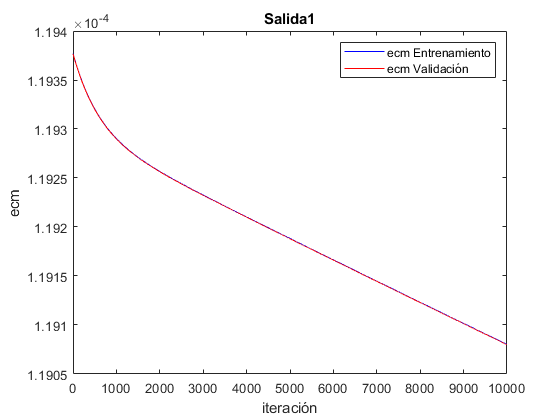

for i = 1:ns
    figure;
    plot(1:nit,ecmTrain(i,:),'b',1:nit,ecmValidacion(i,:),'r');
    xlabel('iteración');
    ylabel('ecm');
    legend('ecm Entrenamiento','ecm Validación')
    title(strcat('Salida ', num2str(i)));
end


% fprintf('ECM Para prueba es: %f \n',[ecmTest])

save('PesosInverso.mat','c2','w2','d2')